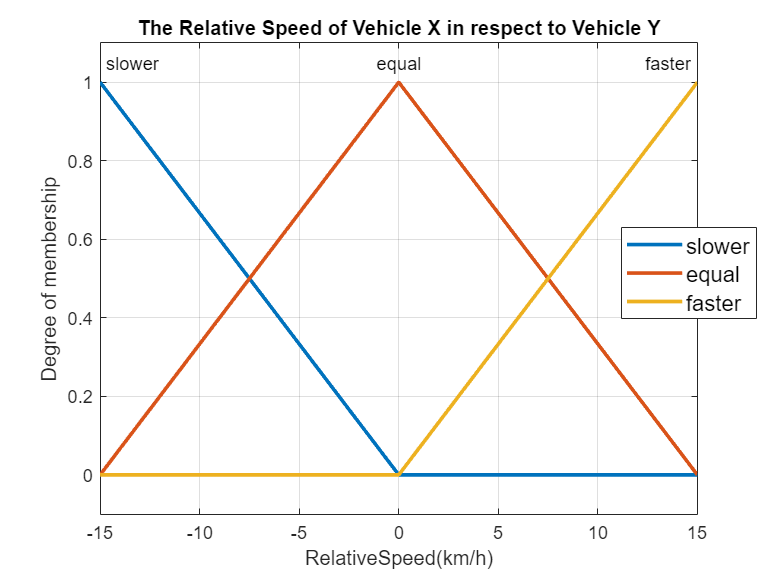

% Create FIS (Fuzzy Inferance System)
% With 1 input (with 3 membership functions) and 1 output (with 3 membership functions)

fuzzyFIS = mamfis(...
    'Name','Uses Binary MFs',...
    'NumInputs',2,'NumInputMFs',3,... % 2 Inputs and 3 Variables required for each input
    'NumOutputs',1,'NumOutputMFs',5,... % 1 Output and 5 variables required 
    'AddRule','none'...
    );

% laser Sensors can reach to a maximum of 200 metres

% Creating Inputs
fuzzyFIS.Inputs(1).Name = 'RelativeSpeed'; % distance difference between the vechiles
fuzzyFIS.Inputs(1).Range = [-15 15];
fuzzyFIS.Inputs(1).MembershipFunctions(1).Name = "slower"; % The linguistic Description
fuzzyFIS.Inputs(1).MembershipFunctions(1).Type = "linzmf"; % The type of graph
fuzzyFIS.Inputs(1).MembershipFunctions(1).Parameters = [-15 0]; % Declares the range
fuzzyFIS.Inputs(1).MembershipFunctions(2).Name = "equal"; % The linguistic Description
fuzzyFIS.Inputs(1).MembershipFunctions(2).Type = "trimf"; % The type of graph
fuzzyFIS.Inputs(1).MembershipFunctions(2).Parameters = [-15 0 15]; % Declares the range
fuzzyFIS.Inputs(1).MembershipFunctions(3).Name = "faster"; % The linguistic Description
fuzzyFIS.Inputs(1).MembershipFunctions(3).Type = "linsmf"; % The type of graph
fuzzyFIS.Inputs(1).MembershipFunctions(3).Parameters = [0 15]; % Declares the range

% Plotting Input MFs
plotmf(fuzzyFIS,'input',1,1000) % the more values, the more accurate !00+ required
set(findall(gca, 'Type', 'Line'), 'lineWidth',2)
grid on

% Updating Graph properties
legend("show")
legend({'slower','equal','faster'},'FontSize',12)
title("The Relative Speed of Vehicle X in respect to Vehicle Y")
xlabel("RelativeSpeed(km/h)")
ylabel("Degree of membership")
legend("Position",[0.80738,0.45032,0.175,0.15476])

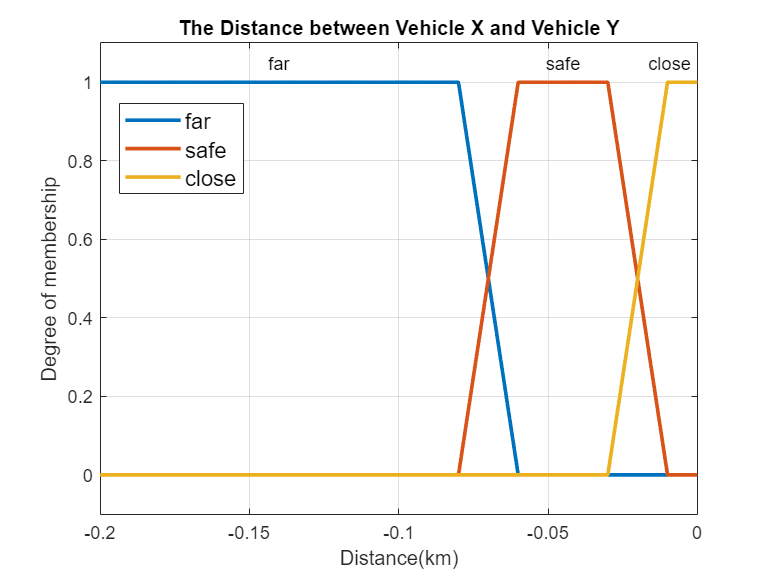


% Creating Inputs
fuzzyFIS.Inputs(2).Name = 'Distance'; % distance difference between the vechiles
fuzzyFIS.Inputs(2).Range = [-0.2 0]; % Modern Day laser sensors can detect to 200 metres in front of them
fuzzyFIS.Inputs(2).MembershipFunctions(1).Name = "far"; % The linguistic Description
fuzzyFIS.Inputs(2).MembershipFunctions(1).Type = "trapmf"; % The type of graph
fuzzyFIS.Inputs(2).MembershipFunctions(1).Parameters = [-0.2 -0.2 -0.08 -0.06]; % Declares the range
fuzzyFIS.Inputs(2).MembershipFunctions(2).Name = "safe"; % The linguistic Description
fuzzyFIS.Inputs(2).MembershipFunctions(2).Type = "trapmf"; % The type of graph
fuzzyFIS.Inputs(2).MembershipFunctions(2).Parameters = [-0.08 -0.06 -0.03 -0.01]; % Declares the range
fuzzyFIS.Inputs(2).MembershipFunctions(3).Name = "close"; % The linguistic Description
fuzzyFIS.Inputs(2).MembershipFunctions(3).Type = "trapmf"; % The type of graph
fuzzyFIS.Inputs(2).MembershipFunctions(3).Parameters = [-0.03 -0.01 0 0]; % Declares the range
plotmf(fuzzyFIS,'input',2,1000) % the more values, the more accurate !00+ required
set(findall(gca, 'Type', 'Line'), 'lineWidth', 2)
grid on

% Updating Graph properties
legend("show")
legend({'far','safe','close'},'FontSize',12)
title("The Distance between Vehicle X and Vehicle Y")
xlabel("Distance(km)")
ylabel("Degree of membership")
legend("Position",[0.15631,0.66556,0.15893,0.15476])

% the Output
fuzzyFIS.Outputs(1).Name = 'Reaction';
fuzzyFIS.Outputs(1).Range = [-15 15];
fuzzyFIS.Outputs(1).MembershipFunctions(1).Name = 'brakeHard';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Type = 'linzmf';
fuzzyFIS.Outputs(1).MembershipFunctions(1).Parameters = [-15 -5];
fuzzyFIS.Outputs(1).MembershipFunctions(2).Name = 'brakeModerately';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Type = 'trimf';
fuzzyFIS.Outputs(1).MembershipFunctions(2).Parameters = [-15 -5 0];
fuzzyFIS.Outputs(1).MembershipFunctions(3).Name = 'maintainSpeed';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Type = 'trimf';
fuzzyFIS.Outputs(1).MembershipFunctions(3).Parameters = [-5 0 5];
fuzzyFIS.Outputs(1).MembershipFunctions(4).Name = 'accelerateModerately';
fuzzyFIS.Outputs(1).MembershipFunctions(4).Type = 'trimf';
fuzzyFIS.Outputs(1).MembershipFunctions(4).Parameters = [0 5 15];
fuzzyFIS.Outputs(1).MembershipFunctions(5).Name = 'accelerateHard';
fuzzyFIS.Outputs(1).MembershipFunctions(5).Type = 'linsmf';
fuzzyFIS.Outputs(1).MembershipFunctions(5).Parameters = [5 15];


legend("Position",[0.15631,0.66556,0.15893,0.15476])

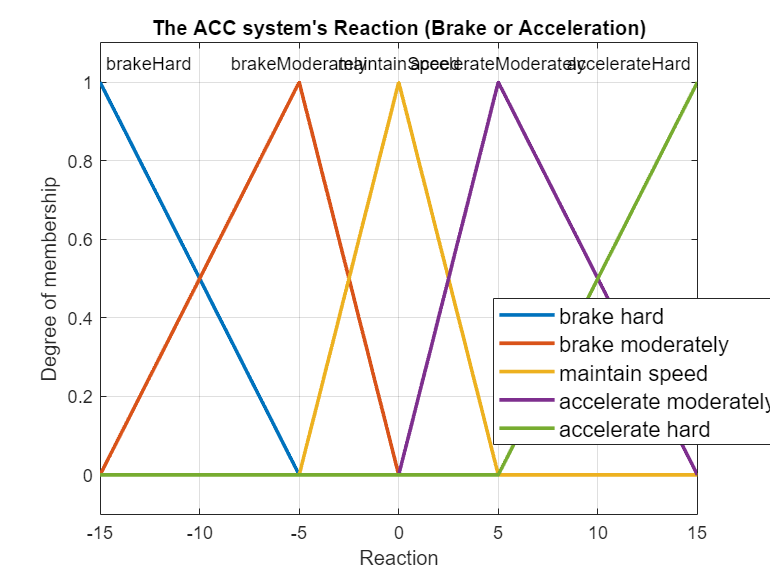

% Plotting these MFs
plotmf(fuzzyFIS,'output',1,1500);
set(findall(gca, 'Type', 'Line'), 'lineWidth', 2);
grid on
% Updating Graph properties
legend("show")
legend({'brake hard','brake moderately','maintain speed', 'accelerate moderately', 'accelerate hard'},'FontSize',12)
title("The ACC system's Reaction (Brake or Acceleration)")
xlabel("Reaction")
ylabel("Degree of membership")
legend("Position",[0.64202,0.23079,0.37321,0.25238])

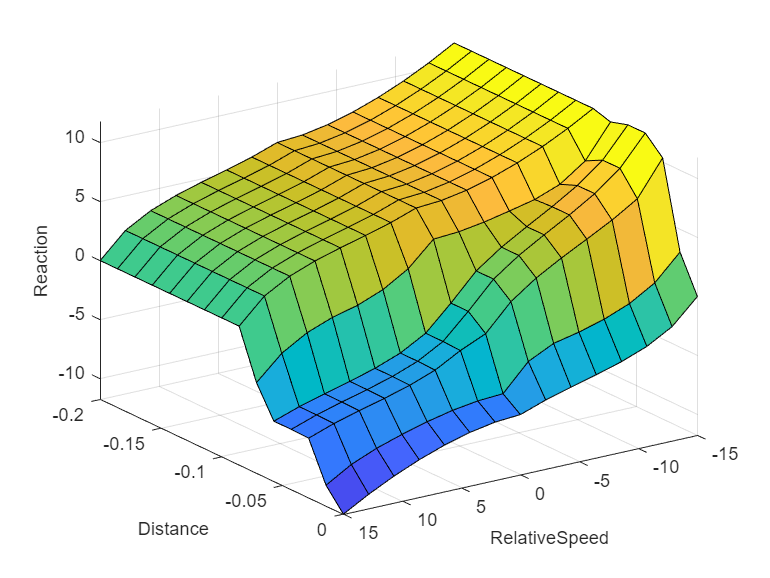



% Declaring the rules for the Fuzzy Inference System (Captisation is important in fuzzification)
% Produces a line which maps credit score to risk

rules = ["if Distance is close and RelativeSpeed is slower then Reaction is maintainSpeed"...
         "if Distance is close and RelativeSpeed is equal then Reaction is brakeModerately"...
         "if Distance is close and RelativeSpeed is faster then Reaction is brakeHard"...
         "if Distance is safe and RelativeSpeed is slower then Reaction is accelerateHard"...
         "if Distance is safe and RelativeSpeed is equal then Reaction is maintainSpeed"...
         "if Distance is safe and RelativeSpeed is faster then Reaction is brakeModerately"...
         "if Distance is far and RelativeSpeed is slower then Reaction is accelerateHard"...
         "if Distance is far and RelativeSpeed is equal then Reaction is accelerateModerately"...
         "if Distance is far and RelativeSpeed is faster then Reaction is maintainSpeed"];

% Adding the values
fuzzyFIS = addRule(fuzzyFIS,rules); 
gensurf(fuzzyFIS);
view([-214.5 26.6])